# GRID WORLD PROBLEM

The grid considered is having 36 cells arranged in 6 rows and 6 columns. A robot can be at any one of the possible cells at any instant. We can refer the cell number as state of the robot. ‘G’ denotes the goal state to which the robot aim to reach and the crossed cells denote cells with some sort of obstacles. There is cost associated with each cell transition while the cost of passing through a cell with obstacle is much higher compared to other cells. Starting from any initial position in the grid, robot can reach the goal cell by following different paths and correspondingly cost incurred will also vary. The problem is to find an optimum path to reach the goal state (cell) starting from any one of the initial state.

In this simple grid world we assume a cost of 1 unit for transition to an ordinary cell while 10 units for a cell having some obstacles.

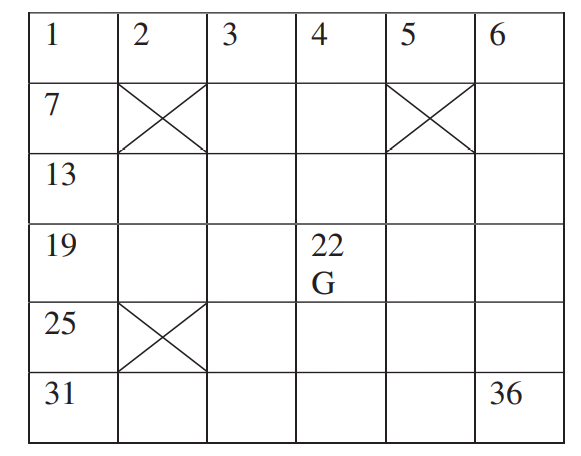

clear

First we need to create a 6*6 sized gridworld.

GW = createGridWorld(6,6)

GW =   GridWorld with properties:

          GridSize: [6 6]
      CurrentState: "[1,1]"
            States: [36×1 string]
           Actions: [4×1 string]
                 T: [36×36×4 double]
                 R: [36×36×4 double]
    ObstacleStates: [0×1 string]
    TerminalStates: [0×1 string]


Now, we need to initialise the current state of the robot, the terminal state and the states which are having obstacles.

GW.CurrentState = '[1,1]';
GW.TerminalStates = '[4,4]';
GW.ObstacleStates = ["[2,2]";"[2,5]";"[5,2]"];

nS = numel(GW.States) %Number of States

nS = 36

nA = numel(GW.Actions) %Number of Actions

nA = 4

The reward(here cost) associated with each action in the given state should be defined.

GW.R = 1*ones(nS,nS,nA); %Fill reward transition matrix with 1.

The cost of getting into a state having obstacle is higher(10).

GW.R(:,state2idx(GW,"[2,2]"),:) = 10;
GW.R(:,state2idx(GW,"[2,5]"),:) = 10;
GW.R(:,state2idx(GW,"[5,2]"),:) = 10;

Now, we need to create a Reinforcement Learning MDP environment.

env = rlMDPEnv(GW)

env =   rlMDPEnv with properties:

       Model: [1×1 rl.env.GridWorld]
    ResetFcn: []


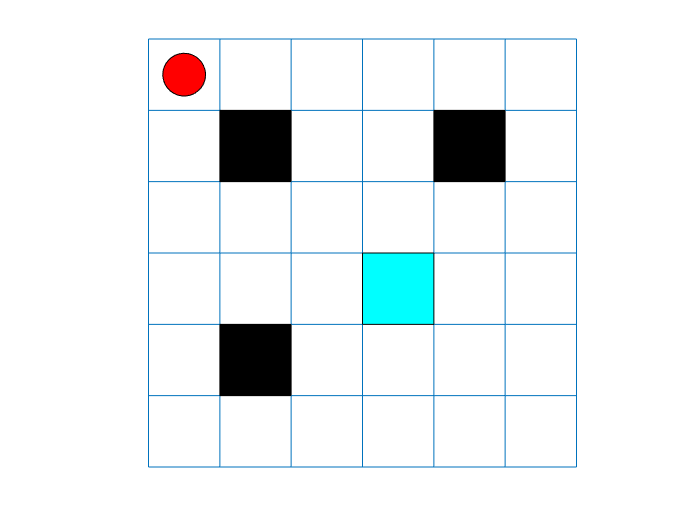

plot(env)